Step 1: Load the data and preprocess it.

clear; close all; clc
% filename = 'SA63_DS_020923_0001'; 
filename = 'SA62_pIC_021023_0000' 

filename = 'SA63_NAc_021023_0001'

ProcessedData = fb_extract(filename, 'Seriers');
% ProcessedData = fb_extract(filename, 'none');
% ProcessedData = fb_extract_gr(filename);


save([filename, '_processed.mat'], 'ProcessedData')

Step2: Visulize the data and convert the event to timestamps

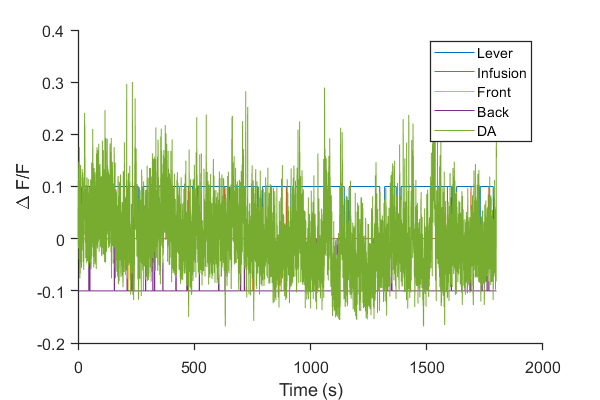

%% do some visualization
clearvars -except ProcessedData filename
i = 1;
figure
h1 = plot(ProcessedData(i).rawDIO.time, 0.1* (ProcessedData(i).rawDIO.lever* -1 + 1));
hold on;
h2 = plot(ProcessedData(i).rawDIO.time, 0.1*(ProcessedData(i).rawDIO.infusion* -1 + 1));
h3 = plot(ProcessedData(i).rawDIO.time, 0.1 *ProcessedData(i).rawDIO.front*-1);
h4 = plot(ProcessedData(i).rawDIO.time, 0.1 * ProcessedData(i).rawDIO.back*-1);
h5 = plot(ProcessedData(i).processed.time, ProcessedData(i).processed.signal);
legend({'Lever', 'Infusion', 'Front', 'Back', 'DA'})
ylabel('\Delta F/F')
xlabel('Time (s)')
box off
set(gca,'TickDir','out')
set(gca,'fontsize',12)
set(gca,'TickLengt', [0.015 0.015]);
set(gca, 'LineWidth',1)
set(gcf,'position',[100,100,600,400])

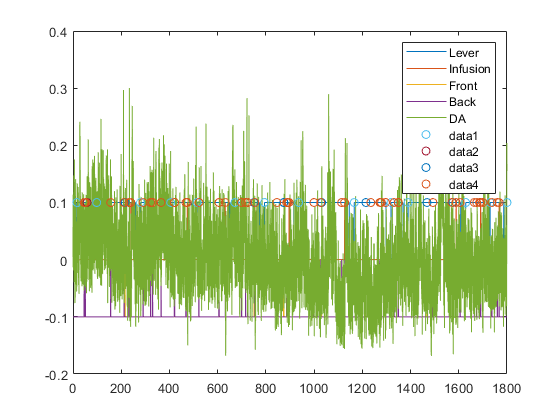

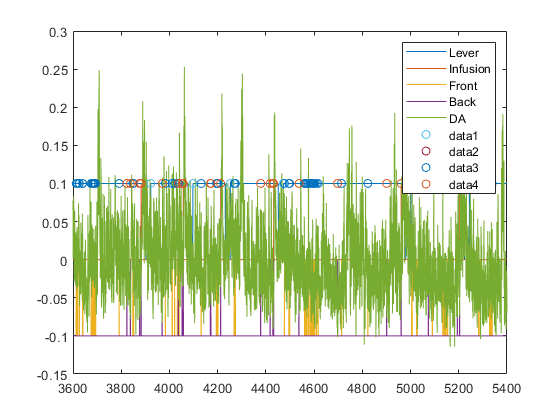

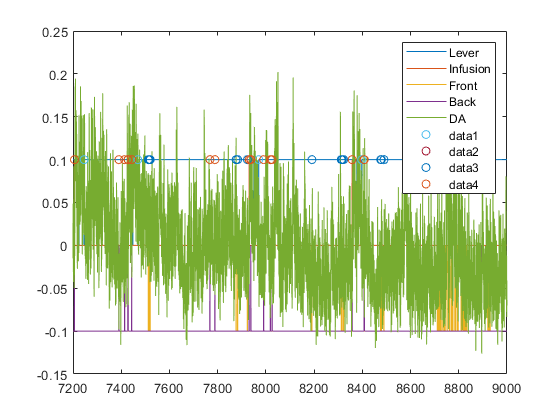


%% get the timestamps of each event.
for i = 1:length(ProcessedData)
    rawDIO = ProcessedData(i).rawDIO;
    [ProcessedData(i).DIO.lever_in, ProcessedData(i).DIO.lever_out]=Timing_onset_offset(rawDIO.lever, rawDIO.time, 0.5,1,0);
    ProcessedData(i).DIO.infusion = med_find_event(rawDIO.infusion, rawDIO.time);
    ProcessedData(i).DIO.front = med_find_event(rawDIO.front, rawDIO.time);
    ProcessedData(i).DIO.back = med_find_event(rawDIO.back, rawDIO.time);  
    figure
    plot(ProcessedData(i).rawDIO.time, 0.1* (ProcessedData(i).rawDIO.lever* -1 + 1));
    hold on;
    plot(ProcessedData(i).rawDIO.time, 0.1*(ProcessedData(i).rawDIO.infusion* -1 + 1));
    plot(ProcessedData(i).rawDIO.time, 0.1 *ProcessedData(i).rawDIO.front*-1);
    plot(ProcessedData(i).rawDIO.time, 0.1 * ProcessedData(i).rawDIO.back*-1);
    plot(ProcessedData(i).processed.time, ProcessedData(i).processed.signal);
    legend({'Lever', 'Infusion', 'Front', 'Back', 'DA'})
    scatter(ProcessedData(i).DIO.lever_out, 0.1 * ones(size(ProcessedData(i).DIO.lever_out)))
    scatter(ProcessedData(i).DIO.infusion, 0.1 *ones(size(ProcessedData(i).DIO.infusion)))
    scatter(ProcessedData(i).DIO.front, 0.1 *ones(size(ProcessedData(i).DIO.front)))
    scatter(ProcessedData(i).DIO.back , 0.1 *ones(size(ProcessedData(i).DIO.back)))
end

Step 3: Concatenate data and plot psth

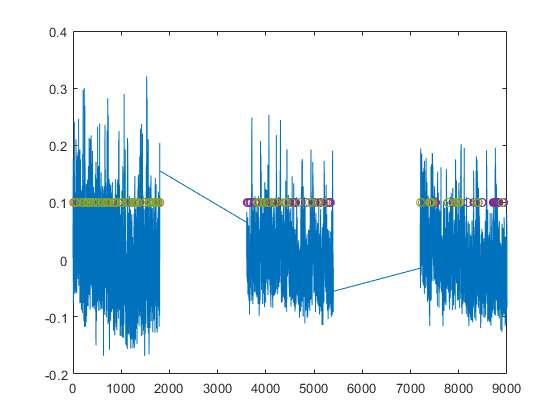

%% plot the psth for fb
% concatenate the data
Signal_concat = [ProcessedData(1).processed.signal;...
                ProcessedData(2).processed.signal; ...
                ProcessedData(3).processed.signal];
Time_concat   = [ProcessedData(1).processed.time;...
                 ProcessedData(2).processed.time;...
                 ProcessedData(3).processed.time];
% concatenate events
for i = 1:length(ProcessedData)
    if i ==1 
        DIO = ProcessedData(1).DIO;
    else
        fields = fieldnames(DIO);
        for k = 1:length(fields)
            DIO.(fields{k}) = [DIO.(fields{k}); ProcessedData(i).DIO.(fields{k})];
        end
    end
end
figure; plot(Time_concat, Signal_concat)
hold on
scatter(DIO.lever_out, 0.1 *ones(size(DIO.lever_out)))
scatter(DIO.infusion, 0.1 *ones(size(DIO.infusion)))
scatter(DIO.front, 0.1 *ones(size(DIO.front)))
scatter(DIO.back , 0.1 *ones(size(DIO.back)))

% save the data
signal = Signal_concat;
time = Time_concat;
save([filename, '_summary.mat'], 'signal', 'time', 'DIO', 'filename')


Plot the psth of the response

event = DIO.lever_in;

Unable to resolve the name DIO.lever_in.

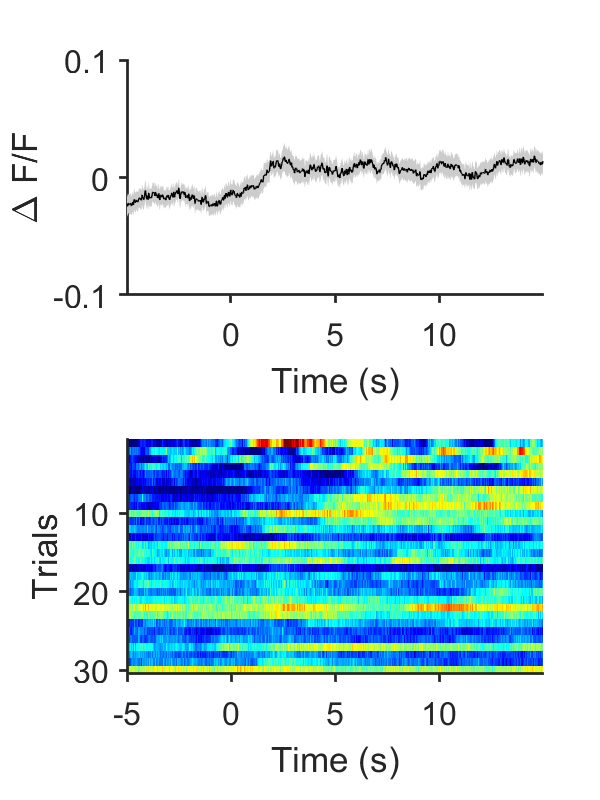

pre = -2; % in secs
post= 45; % in secs
[psth_time,psth_signal] = psth_fb(signal,time, event, pre, post);

Detrend the signals

signal_dtrend = [detrend(ProcessedData(1).processed.signal,3);...
    detrend(ProcessedData(2).processed.signal,3); ...
    detrend(ProcessedData(3).processed.signal,3)];
time   = [ProcessedData(1).processed.time;...
                 ProcessedData(2).processed.time;...
                 ProcessedData(3).processed.time];
save([filename, '_summary_dtrend.mat'], 'signal_dtrend', 'time', 'DIO', 'filename')


Summarize the data for each animal:

clear; close all, clc
datadir = 'H:\Data\FB_data\';
animalID = 'SA57';
sessions = {'20230119', '20230120', '20230124', '20230126', '20230131', '20230202', '20230209', '20230210'};
cd([datadir, animalID])
datasum = [];
for i = 1:length(sessions)
    filedir = [datadir, animalID, '\', sessions{i}];
    cd(filedir)
    file_processed = dir('*_processed.mat');
    file_summary  = dir('*_summary.mat');
    file_split = strsplit(file_summary.name, '_');
    region = file_split{2};
    load(file_processed.name)
    load(file_summary.name)
    datasum(i).animalID     = animalID;
    datasum(i).session      = sessions{i};
    datasum(i).filename     = filename;
    datasum(i).session_note = [];
    datasum(i).region       = region;
    datasum(i).rawdata      = ProcessedData;
    datasum(i).signal       = signal;
    datasum(i).time         = time;
    datasum(i).DIO          = DIO;    
end
